# BME 2740 Interactive Lecture 18

# By: Dr Asad Mirza

# Adapted From: Dr Ilmar Tamames

#### Local Maxima/Minima

Newton’s method for function minimization is prone to falling to a local point instead of the intended goal. The points x* at which $f^{\prime } \left(x\right)$ equals zero are called critical points or stationary points. At a critical point x*, the function is parallel with the x-axis. Three possibilities arise regarding the nature of the critical point x*:

(1) $f^{\prime \prime } \left(x\right)>0$,the point is a local minimum.

(2) $f^{\prime \prime } \left(x\right)\;<0$,the point is a local maximum.

(3) $f^{\prime \prime } \left(x\right)\;==0$, the point may be either an inflection point or an extreme point. As such, this test is inconclusive. The values of higher derivatives (${f^{\prime \prime } }^{\prime } \left(x\right)$ and up) are needed to define this point. If $f^k \left(x\right)$ is the first nonzero kth derivative, then if k is even, the point is an extremum (minimum if $f^k \left(x\right)$, else maximum), and if k is odd, the critical point is an inflection point.

#### Example 1: 

Let's say we have a function:


$$f\left(x\right)=\frac{x^2 \cos \left(x\right)-x}{10}$$


And we're trying to find the maximum (or minimum) near 5 with a tolerance of 0.01. Your span is from -12 to 12.

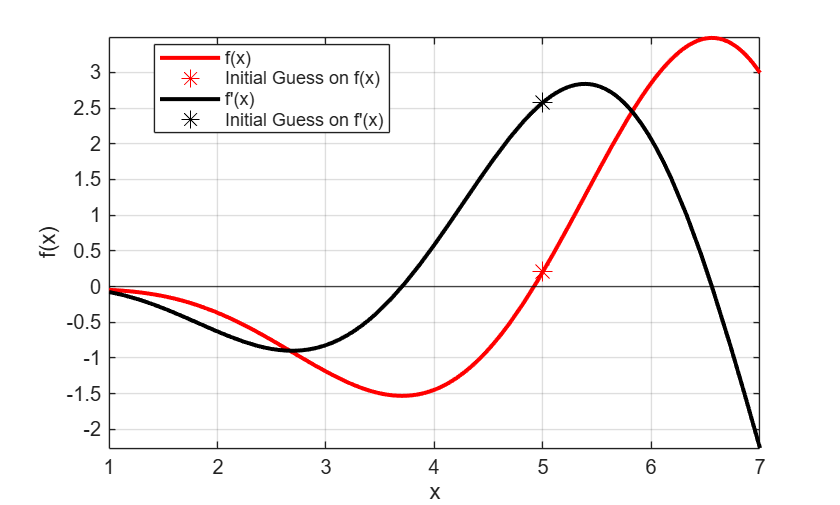

clear; clc; close all;  % Clear workspace, command window, and close all figures

% Setup variables
tolx = 0.01;           % Convergence tolerance for optimization (not used here yet)
x0 = 5;                % Initial guess for the optimization
tspan = [-12, 12];     % Range for plotting the function from x = -12 to x = 12
maxloops = 20;         % Maximum number of iterations

% Define the function and its derivatives symbolically
syms f(x);                  % Declare symbolic variable x
f(x) = (1/10) * ((x.^2) .* cos(x) - x);  % Function definition: f(x) = (1/10) * (x^2 * cos(x) - x)
dfx(x) = diff(f, x);               % First derivative of f(x), f'(x) = df/dx
d2fx(x) = diff(f, x, 2);           % Second derivative of f(x), f''(x) = d²f/dx²

% Convert to MATLAB Functions
f=matlabFunction(f);
dfx=matlabFunction(dfx);
d2fx=matlabFunction(d2fx);

% Plot the function f(x) and its derivative f'(x)
fplot(f, tspan, 'r', 'LineWidth', 2);     % Plot f(x) in red
hold on;  % Keep the current plot to overlay other graphs

% Plot the initial guess point on f(x)
plot(x0, f(x0), 'r*', 'MarkerSize', 10);  % Mark initial guess on the function in magenta

% Plot the first derivative f'(x) in black
fplot(dfx, tspan, 'k', 'LineWidth', 2);   % Plot f'(x) in black

% Plot the initial guess point on f'(x)
plot(x0, dfx(x0), 'k*', 'MarkerSize', 10);  % Mark initial guess on the first derivative in blue

% Label axes and add grid and horizontal line at y=0
ylabel('f(x)');  % Label y-axis
xlabel('x');     % Label x-axis
grid on;         % Add grid for better visualization
xlim([1 7]);     % Set x-axis limits to focus on the region from 1 to 7
yline(0, 'k');   % Add a horizontal line at y = 0 (black) to represent the x-axis
% Add legend to describe each plotted element
legend('f(x)', 'Initial Guess on f(x)', 'f''(x)', 'Initial Guess on f''(x)', 'Location', 'best');

% Run the optimization to find local minima or maxima using Newton's Method
tic  % Start timer for performance analysis
for i = 1:maxloops
    % Pause to prevent the plot from updating too quickly
    % pause(2)
    
    % Update the plot with the current guess point
    plot(x0, f(x0), 'r*', 'MarkerSize', 10);
    plot(x0, dfx(x0), 'k*', 'MarkerSize', 10);
    legend('f(x)', 'Guess for f(x0)', 'f''(x)', 'Guess for f''(x0)', 'Location', 'best');
    % Update the guess using Newton's method: x1 = x0 - f'(x0)/f''(x0)
    x1 = x0 - dfx(x0) / d2fx(x0);  % Evaluate the next guess

    % Display iteration info
    if i == 1
        fprintf('Ite     X0     X1     Dx      DFx     D2Fx\n');
    end
    fprintf('%2d %7.3f %7.3f %7.3f %7.3f %7.3f\n', i, x0, x1, abs(x1-x0), dfx(x0), d2fx(x0));

    % Check for convergence: if the change in x is less than tolerance
    if abs(x1 - x0) <= tolx
        % Classify the critical point based on the second derivative (D2Fx)
        if d2fx(x0)> 0
            disp('Local Minimum');
        else
            disp('Local Maximum');
        end
        break  % Exit the loop if converged
    end

    % Update the guess for the next iteration
    x0 = x1;

    % Update the plot
    drawnow;  % Optionally comment out if not needed for performance reasons
end

Ite     X0     X1     Dx      DFx     D2Fx


 1   5.000   2.960   2.040   2.581   1.265
 2   2.960   4.820   1.859  -0.840   0.452
 3   4.820   3.450   1.369   2.313   1.689
 4   3.450   3.741   0.290  -0.396   1.363
 5   3.741   3.702   0.039   0.071   1.834
 6   3.702   3.701   0.001   0.001   1.778


Local Minimum


toc  % Stop the timer

Elapsed time is 0.796705 seconds.


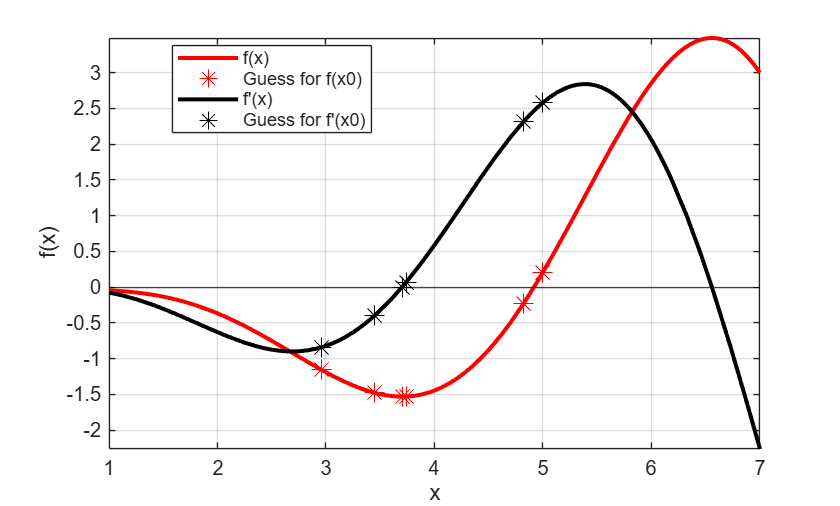

hold off;  % Release the plot hold to prevent further plotting on the same figure

When calculating a local maximum/minimum, the method can sometimes fail to converge promptly. This can be due to a number of reasons such as: poor initial guess, flat/near zero 1st derivative of f(x), multiple local min/maxes, flat/near zero 2nd derivative of f(x).

#### Method of Gradient Descent

The Gradient Descent Method or Standard Gradient Descent (SGD) refers to the procedure of looking around your landscape, wherever you happen to be at the moment, and “taking a step” in the direction of the steepest incline (based on your derivative/gradient). However, YOU control the speed of stepping rather than letting the derivative/gradient dictate the size.

Formally:


$$x_{k+1} =x_k -\alpha \nabla f{\left(x_k \right)}$$


The size of the step you take on the the hill is α, and $\nabla f{\left(x_k \right)}$is the gradient (derivative) of $f{\left(x_k \right)}$.

clear; clc; close all;

% Define grid for 3D surface plot
x = -10:1:10;   % X range
y = -10:1:10;   % Y range
alpha = 0.02;   % Learning rate for gradient descent

% Create meshgrid
[X, Y] = meshgrid(x, y);
f = @(X,Y) X.^2 + Y.^2;  % Function: Paraboloid

% Plot the surface
figure
surf(X, Y, f(X,Y), 'EdgeColor', 'none');  % Remove grid lines for cleaner look
hold on;
colormap(jet);  % Apply color gradient
view(5, 60);         % Adjust view (azimuth, elevation)
xlabel('X-axis'); ylabel('Y-axis'); zlabel('f(X, Y)');
title('Gradient Descent Optimization');
colorbar;  % Add color scale for visualization

% Initialize starting point
x0 = [10, 10];  % Initial guess
plot3(x0(1), x0(2), f(x0(1),x0(2)), 'm*', 'MarkerSize', 15); % Plot start point

% Gradient Descent Loop
tic
for i = 1:50
    % Compute gradient: [df/dx, df/dy] = [2x, 2y]
    grad = 2 * x0;
    
    % Update position using gradient descent step
    x1 = x0 - alpha * grad;

    % Update x0 for next iteration
    x0 = x1;
    
    % Plot the updated point
    plot3(x0(1), x0(2), f(x0(1),x0(2)), 'm*', 'MarkerSize', 10);
    drawnow;
end
toc

Elapsed time is 1.425582 seconds.


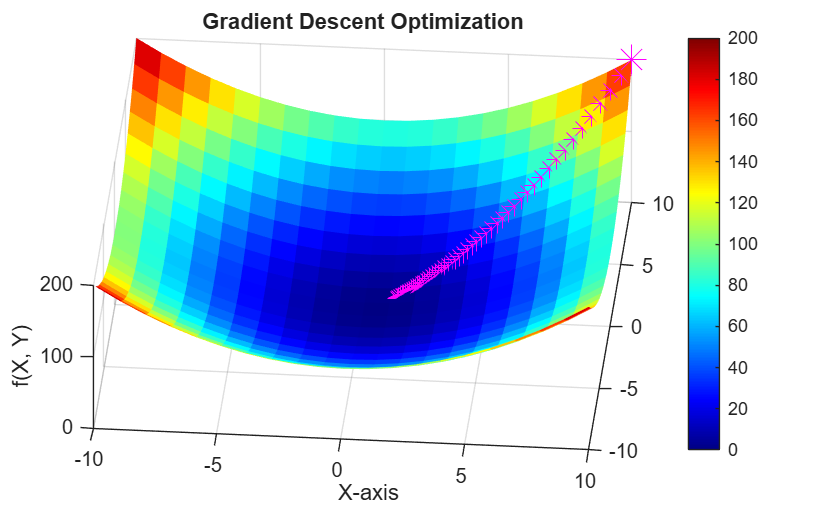

hold off;

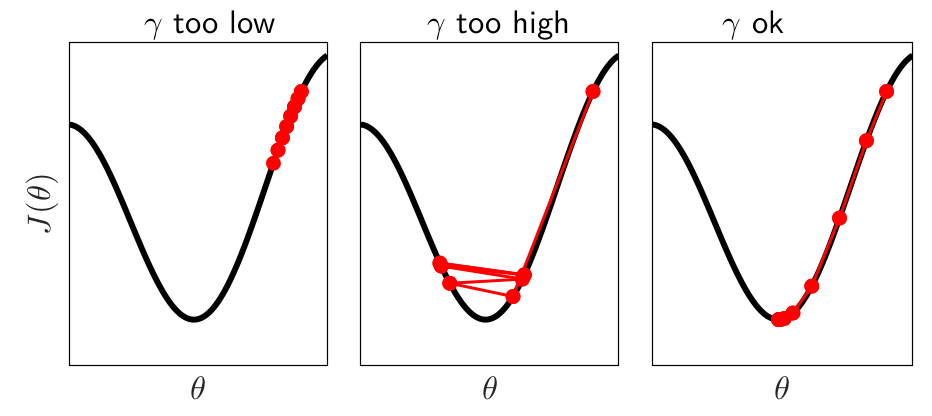

You want to select a learning rate, $\alpha \;$or sometimes labeled as $\gamma$, that isn't too big but also not too small.

Steps for Gradient Descent Method or Standard Gradient Descent (SGD) :

- Select an initial guess $x_0$.

- Evaluate $-\nabla f{\left(x_k \right)}\;$. This provides the search direction $s_k =\nabla f{\left(x_k \right)}\;$.

- Perform a single-variable optimization to minimize $f\left(x_k +\alpha s_k \right)$, meaning apply Newton's Method on it.

- Calculate the new point $x_{k+1} =x_k +\alpha s_k$.

- Repeat 2-4 until convergence.

Since the method searches for a critical point, it is possible that the iterations may converge upon a saddle point. Therefore, it is important to verify the nature of the critical point by confirming whether the second derivative evaluated at the final point is positive or negative.

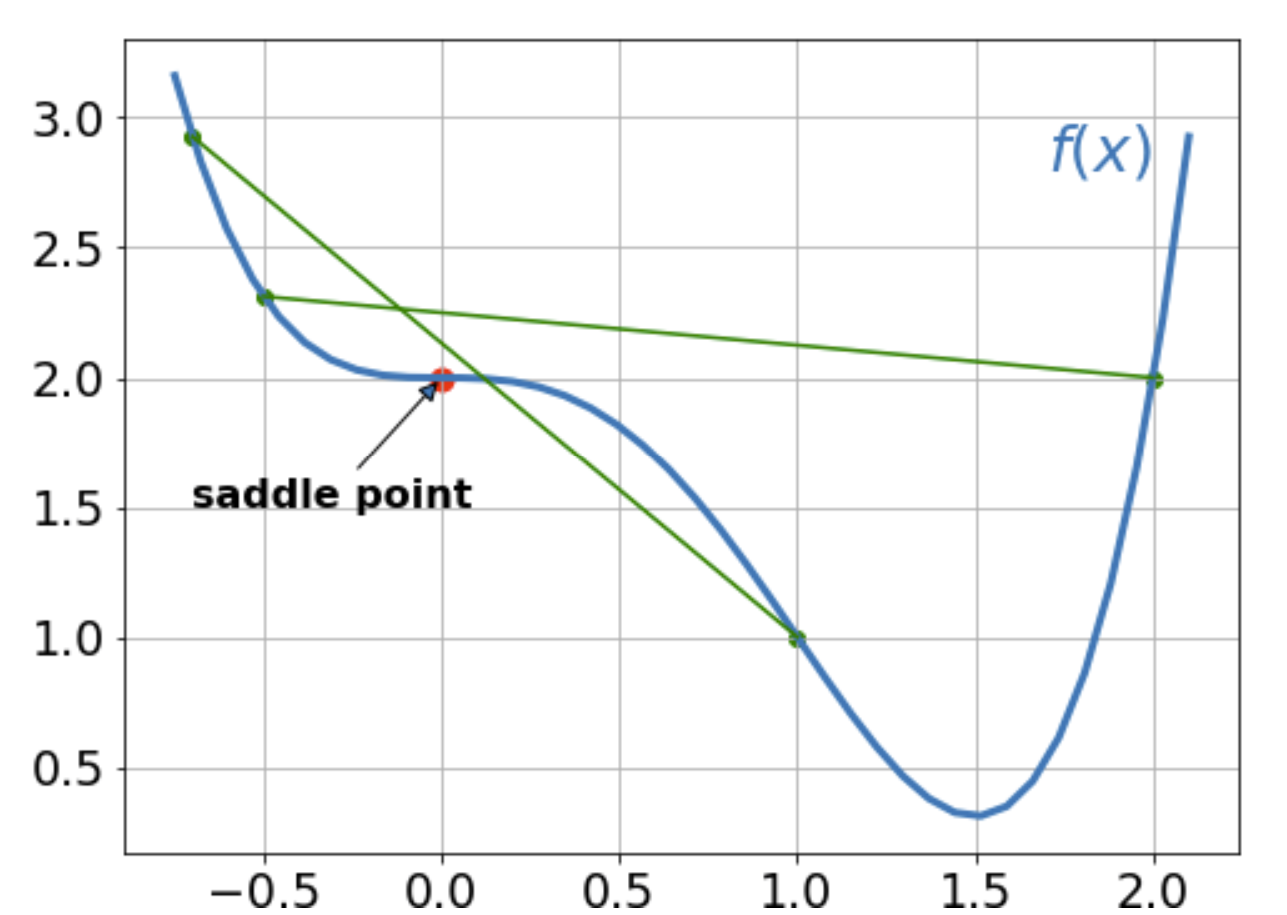

An advantage of the descent method is that a good initial approximation to the minimum is not required for this method to proceed towards a critical point. The adjustable learning rate, $\alpha \;$, dictates the speed of solution convergence at the cost of stability. 

#### Example 2:

Activity: Write the SGD code needed to find the minimum of:


$$f\left(x\right)=\frac{x^2 \cos \left(x\right)-x}{10}$$


Near 5 with a tolerance of 0.01. Your span is from -12 to 12. Try alpha of .2.

clear; clc; close all;

% Setup parameters
tolx = 0.01;    % Convergence tolerance
alpha = 0.2;    % Learning rate (step size)
x0 = 6;         % Initial guess (try -6, 0, etc.)
tspan = [-12, 12];  % Range for function plot
maxloops = 50;  % Maximum number of iterations

% Define the function
syms x;
f(x) = (1/10) * ((x.^2) .* cos(x) - x);  % Function
dfx(x) = gradient(f, x);                 % First derivative (gradient)
d2fx(x) = diff(f, x, 2);                  % Second derivative

% Convert to MATLAB Functions
f=matlabFunction(f);
dfx=matlabFunction(dfx);
d2fx=matlabFunction(d2fx);

% Plot function
figure;
fplot(f, tspan, 'LineWidth', 2);
xlabel('x'); ylabel('f(x)'); title('Gradient Descent Optimization');
grid on;
hold on;

% Gradient Descent Iteration
tic
for i = 1:maxloops
    % Plot the current point
    plot(x0, f(x0), 'mo', 'MarkerSize', 10, 'LineWidth', 1.5);

    % Compute gradient step
    grad = dfx(x0);
    x1 = x0 - alpha * grad;

    % Display iteration details
    if i == 1
        fprintf('Ite   X0     X1     DFx     D2Fx\n');
    end
    fprintf('%2d %7.3f %7.3f %7.3f %7.3f\n', i, x0, x1, grad, d2fx(x0));

    % Check for convergence
    if abs(x1 - x0) <= tolx || abs(grad) < tolx
        if d2fx(x0) > 0
            disp('Local Minimum');
        else
            disp('Local Maximum');
        end
        break;
    end
    
    % Update x0
    x0 = x1;
end

Ite   X0     X1     DFx     D2Fx


 1   6.000   5.588   2.058  -2.594
 2   5.588   5.037   2.758  -0.814
 3   5.037   4.512   2.626   1.165
 4   4.512   4.169   1.715   2.134
 5   4.169   3.978   0.956   2.223
 6   3.978   3.869   0.540   2.107
 7   3.869   3.806   0.318   1.998
 8   3.806   3.767   0.193   1.921
 9   3.767   3.743   0.120   1.871
10   3.743   3.728   0.076   1.837
11   3.728   3.718   0.048   1.816


Local Minimum


toc

Elapsed time is 0.022207 seconds.



% Display final result
fprintf('Final x value: %.4f\n', x1);

Final x value: 3.7184


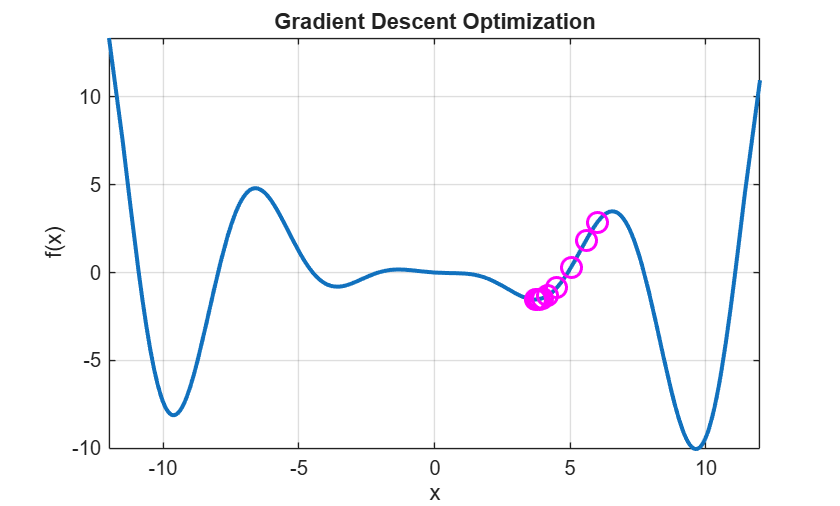

hold off;

It can also be used to find the maximum, all you need to do is change the sign of the gradient:

$\nabla f{\left(x_k \right)}$ instead of $-\nabla f{\left(x_k \right)}$

Positive gradients make the initial guess go up a function, negative gradients make them go down a function.

#### Example 3:

Use SGD code needed to find the maximum of:


$$f\left(x\right)=\frac{x^5 }{6}-2x^4 -x^3 +2x^2 +1$$


Near -1 with a tolerance of 0.01. Your span is from -2 to 2.

clear; clc; clf;

% Setup parameters
tolx = 0.01;     % Convergence tolerance
alpha = 0.02;    % Learning rate (step size)
x0 = -1.5;       % Initial guess (try -0.5, -2, etc.)
tspan = [-2, 2]; % Range for plotting the function
maxloops = 50;   % Maximum iterations

% Define the function and derivatives
syms x;
f(x) = (1/6) * x.^5 - 2 * x.^4 - x.^3 + 2 * x.^2 + 1; % Objective function
dfx(x) = gradient(f, x);  % First derivative (gradient)
d2fx(x) = diff(f, x, 2);  % Second derivative (hessian)

% Convert to MATLAB Functions
f=matlabFunction(f);
dfx=matlabFunction(dfx);
d2fx=matlabFunction(d2fx);

% Plot function
figure;
fplot(f, tspan, 'LineWidth', 2);
xlabel('x'); ylabel('f(x)'); title('Gradient Ascent for Maximum');
grid on; hold on;

% Gradient ascent iteration
tic
for i = 1:maxloops
    % Plot current guess
    plot(x0, f(x0), 'mo', 'MarkerSize', 10, 'LineWidth', 1.5);

    % Compute gradient step
    grad = dfx(x0);
    x1 = x0 + alpha * grad;

    % Display iteration details
    if i == 1
        fprintf('Ite   X0     X1     GFx     D2Fx\n');
    end
    fprintf('%2d %7.3f %7.3f %7.3f %7.3f\n', i, x0, x1, grad, d2fx(x0));

    % Check for convergence
    if abs(x1 - x0) <= tolx || abs(grad) < tolx
        if d2fx(x1) < 0
            disp('Local Maximum');
        else
            disp('Local Minimum');
        end
        break;
    end
    
    % Update x0
    x0 = x1;
end

Ite   X0     X1     GFx     D2Fx


 1  -1.500  -1.131  18.469 -52.250
 2  -1.131  -1.039   4.567 -24.713
 3  -1.039  -0.988   2.555 -19.429
 4  -0.988  -0.956   1.632 -16.724
 5  -0.956  -0.933   1.113 -15.089
 6  -0.933  -0.917   0.789 -14.014
 7  -0.917  -0.906   0.574 -13.273
 8  -0.906  -0.898   0.425 -12.744


Local Maximum


toc

Elapsed time is 0.019545 seconds.



% Display final result
fprintf('Final x value (local max): %.4f\n', x1);

Final x value (local max): -0.8975


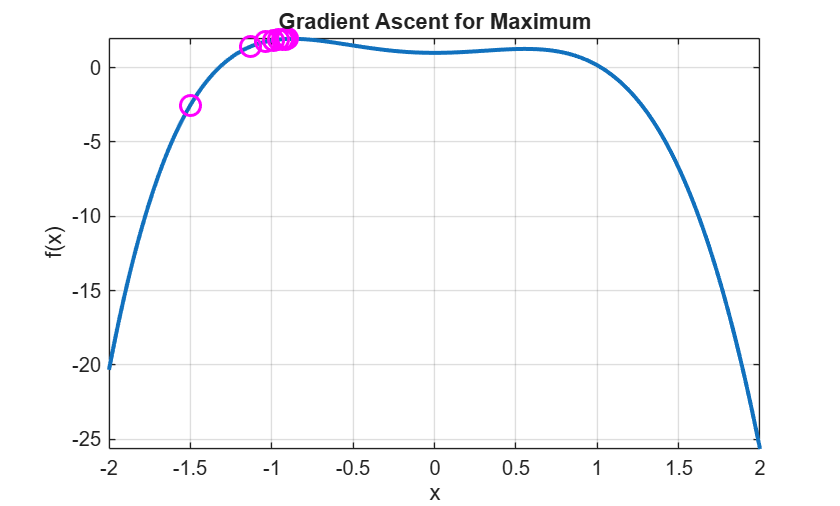

hold off;

## Optimization as Nonlinear Regression

When computing model parameters in linear systems we used the normal equations for over-determined problems to obtain THE optimal solution for using the normal equations.


$$\beta ={\left(X^T X\right)}^{-1} X^T y\;$$


Instead of building a function that represents a process you wish to optimize, we could build a function that is tracking how much error we accrue given a set of parameters that we choose.

The objective function in this case that is typically chosen is the sum of squared error that we've seen before.


$$SSE=\sum_i^m {{\left(y_i -{\hat{y} }_i \right)}}^2$$


Given the model parameters you pick, your success at fitting the data will be quantified by the SSE objective function.

There is (typically) no differentiable form of this expression that we may use for Newton’s method. Also it may also be impossible to compute the error gradient needed for gradient descent. 

#### Simplex method

The Nelder-Mead simplex method is a direct method of minimization since only function evaluations $f{\left(\vec{x_k } \right)}$ , and not function derivatives, are required to proceed iteratively towards the minimum point. 

It works with a simplex, a set of n+1 points in n-dimensional space (triangle in 2D, tetrahedron in 3D, …).

Each iteration it evaluates the objective at the simplex vertices, then tries to move the simplex away from the worst vertex by applying a few simple geometric operations: reflection, expansion, contraction, and shrink.

- **Reflection**: reflect the worst point through the centroid of the other points (tries a step away from the bad point).

- **Expansion**: if reflection is very good, try going further in that direction.

- **Contraction**: if reflection is poor, step only partway toward the centroid.

- **Shrink**: if nothing helps, contract the whole simplex toward the best point (reduces scale).

Repeat until the simplex gets small (converged) or max iterations reached.

The function minima is found using [fminsearch,](https://www.mathworks.com/help/matlab/ref/fminsearch.html) which starts at the point `x0` and attempts to find a local minimum `x` of the function described in `fun`.

#### Example 1:

For the function:


$$f\left(x\right)=\frac{x^2 \cos \left(x\right)-x}{10}$$


Find the minimum near 5. Plot the solution from -12 to 12.

clear,clc
% Setup variables
x0 = 8;               % Initial guess for the optimization (try different values like -6, 0, etc.)
tspan = [-12, 12];     % Range for plotting the function
% Define the objective function
f = @(x) (1/10) * ((x.^2) .* cos(x) - x);  % The function to minimize
% Plot the function to visualize it
figure
fplot(f, tspan, 'LineWidth', 2);  % Plot f(x) over the range tspan
xlabel('x');                      % Label the x-axis
ylabel('f(x)');                   % Label the y-axis
grid on;                          % Display grid on the plot
% Find the minimum of the function using fminsearch
xm = fminsearch(f,x0);  % fminsearch minimizes the function f(x) using the Simplex Method
% Plot the result (minimum) as a point on the curve
hold on;
plot(xm, f(xm), 'r.', 'MarkerSize', 30);  % Plot the minimum as a circle
hold off;

Funny enough you could also use this function to find the nearest maximum.

How? 

Flip the function upside down! 

Now all mins are maxes and all maxes are mins.

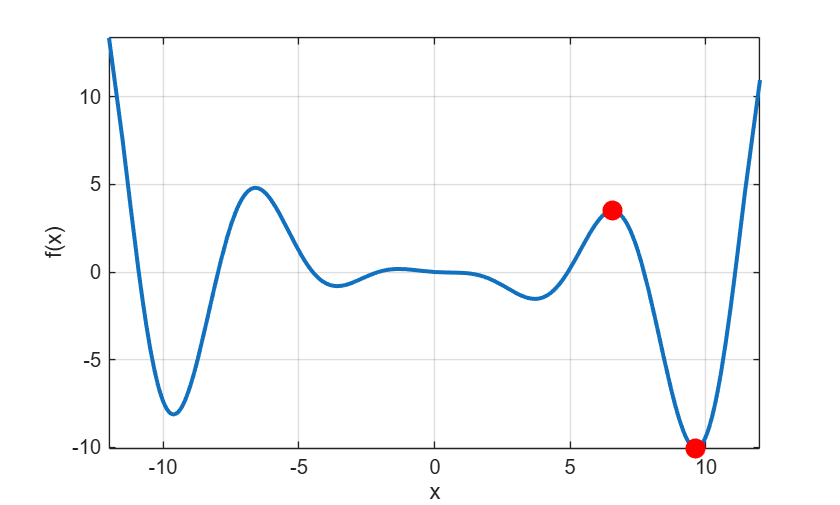

% Define the objective function flipped
f_flipped = @(x) -f(x);  % The function to minimize
xm = fminsearch(f_flipped,x0);  % fminsearch minimizes the function f(x) using the Simplex Method
% Plot the result (maximum) as a point on the curve
hold on;
plot(xm, f(xm), 'r.', 'MarkerSize', 30);  % Plot the minimum as a circle
hold off;

TIP: [fminsearch](https://www.mathworks.com/help/matlab/ref/fminsearch.html)

#### Example 2: Nonlinear Regression: 

Due to a mutation of the Macarena Valley Fever (MVF) virus that typically affects only animal populations, a human outbreak has developed outside of Atlanta. As an engineer working at the CDC, your team has developed a gold nanoparticle drug delivery system to eradicate MVF; however, the treatment is expensive and you wish to determine the minimum possible dose to eliminate the virus to ensure enough is available for all who need it. The CDC biology team supplies you with a dataset of 250 dose-response points they have tested. 


$$R{\left(d\right)}=\frac{{\left(r_m -r_0 \right)}}{1+{{\left(\frac{r_{50} }{d}\right)}}^n }+r_0$$


Where r is the magnitude of the response, as in $r_0$ is unaided recovery rate, $r_m$ is max response,$r_{50}$ is 50% of the max response and the Hill coefficient ( transition rate to max) is denoted by n.

You decide to use this data to fit the classic dose-response Hill function to determine the minimum required dose.

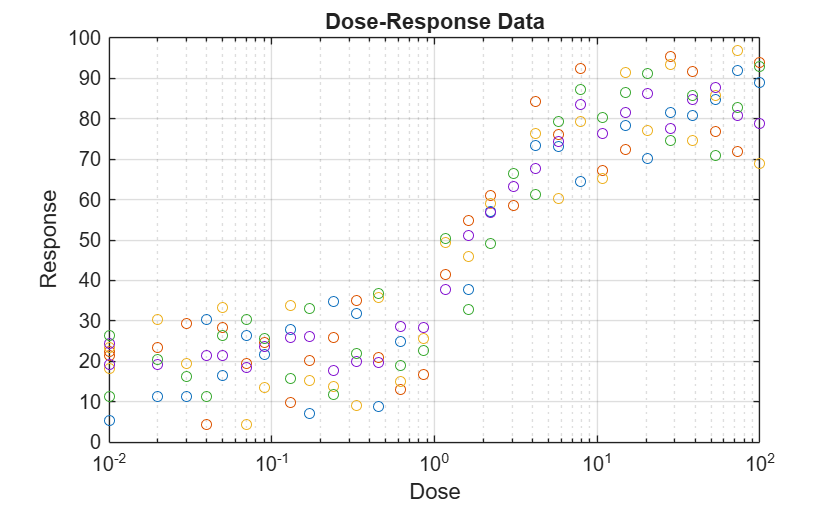

clear, clc  
% Dose data (input)  
di = [0.01 0.01 0.02 0.03 0.04 0.05 0.07 0.09 0.13 0.17 0.24 0.33 0.45 0.62 0.85 1.17 1.61 2.21 3.04 4.18 5.74 7.88 10.83 14.87 20.43 28.07 38.57 52.98 72.79 100.00];  % Doses  

% Response data (multiple measurements for each dose)  
Rd = [23.31  5.31  11.32 11.33 30.35 16.39 26.46 21.58 27.79  7.17 34.82 31.94  8.84 24.93 25.68 41.41 37.87 57.05 66.57 73.38 73.21 64.36 80.30 78.44 70.11 81.50 80.71 84.84 91.91 88.95;  
      21.31 22.31 23.32 29.33  4.35 28.39 19.46 24.58  9.79 20.17 25.82 34.94 20.84 12.93 16.68 41.41 54.87 61.05 58.57 84.38 76.21 92.36 67.30 72.44 91.11 95.50 91.71 76.84 71.91 93.95;  
      18.31 23.31 30.32 19.33 11.35 33.39  4.46 13.58 33.79 15.17 13.82  8.94 35.84 14.93 25.68 49.41 45.87 59.05 66.57 76.38 60.21 79.36 65.30 91.44 77.11 93.50 74.71 85.84 96.91 68.95;  
      19.30 24.31 19.32 16.33 21.35 21.39 18.45 23.57 25.78 26.14 17.77 19.86 19.70 28.69 28.30 37.82 51.02 56.92 63.17 67.77 74.45 83.50 76.38 81.49 86.14 77.51 84.72 87.84 80.91 78.95;  
      11.31 26.31 20.32 16.33 11.35 26.39 30.46 25.58 15.79 33.17 11.82 21.94 36.84 18.93 22.68 50.41 32.87 49.05 66.57 61.38 79.21 87.36 80.30 86.44 91.11 74.50 85.71 70.84 82.91 92.95];  

% Plotting the measured data  
figure  
semilogx(di, Rd, 'o', 'MarkerSize', 5);  % Logarithmic x-axis scatter plot  
hold on
xlabel('Dose')  
ylabel('Response')  
title('Dose-Response Data')  
grid on  % Add grid for better readability  

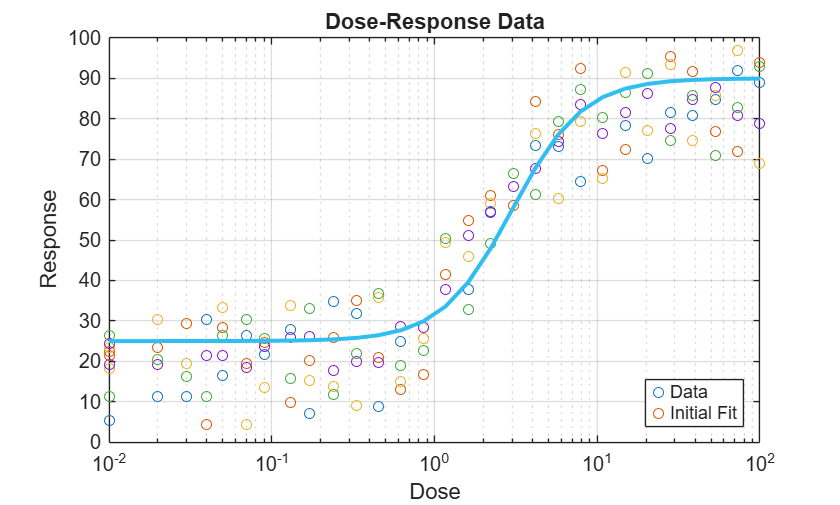

% Initial guesses for the model parameters
rm = 90;     % Max response
r0 = 25;     % Base response
r50 = 3;     % Dose at which the response is half of max
n = 2;       % Hill coefficient (controls the steepness of the curve)
Coef = [rm, r0, r50, n];  % Combine guesses into a parameter vector

% Define the dose-response model function using the Hill equation
Rf = @(d, c) (c(1) - c(2)) ./ (1 + (c(3) ./ d).^c(4)) + c(2);  % Hill equation

% Plot the model using the guessed parameters
semilogx(di, Rf(di, Coef), 'LineWidth', 2);  % Plot model fit based on guessed parameters  
legend('Data', 'Initial Fit', 'Location', 'southeast');  % Add a legend

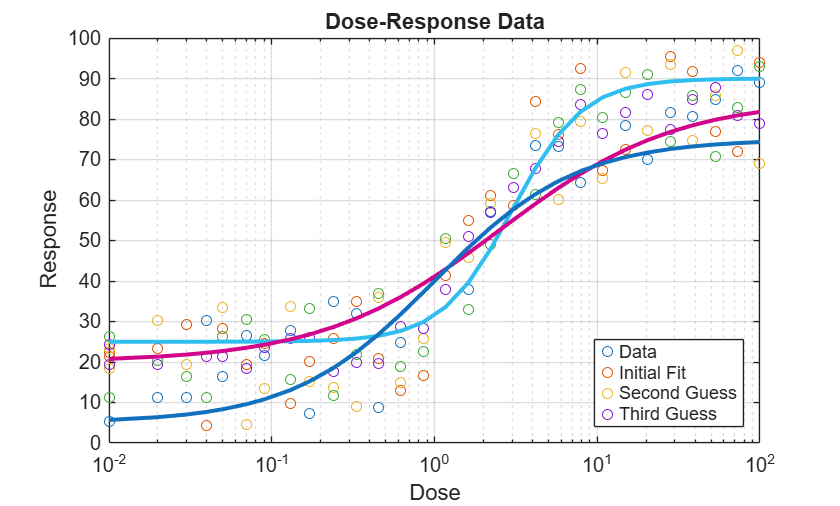

% Plot with a few other sets of parameters to compare
semilogx(di, Rf(di, [85 20 2.5 0.8]), 'LineWidth', 2, 'DisplayName', 'Second Guess');  % Second guess set of parameters
semilogx(di, Rf(di, [75 5 1 1]), 'LineWidth', 2, 'DisplayName', 'Third Guess');    % Third guess set of parameters
% Finalize plot
legend('Data', 'Initial Fit', 'Second Guess', 'Third Guess', 'Location', 'southeast');  % Add a legend
hold off;  % Release the plot hold

How can we find the perfect minimal dose coefficients?

#### Perform Parameter Optimization

% Dose-Response Curve Fitting using the Hill Function
% This script optimizes the parameters of a dose-response model 
% using experimental data and the Hill equation.
% The goal is to determine the minimum required dose to achieve 
% a 50% maximum response (r50).
clear; close all; clc;
% Load Dose-Response Data
% di  - dose levels
% Rd  - response data (5 replicates for each dose)
di = [0.01 0.01 0.02 0.03 0.04 0.05 0.07 0.09 0.13 0.17 0.24 0.33 0.45 0.62 0.85 1.17 1.61 2.21 3.04 4.18 ...
      5.74 7.88 10.83 14.87 20.43 28.07 38.57 52.98 72.79 100.00];

Rd = [23.31  5.31  11.32 11.33 30.35 16.39 26.46 21.58 27.79  7.17 34.82 31.94  8.84 24.93 25.68 41.41 37.87 57.05 66.57 73.38 ...
      73.21 64.36 80.30 78.44 70.11 81.50 80.71 84.84 91.91 88.95;
      21.31 22.31 23.32 29.33  4.35 28.39 19.46 24.58  9.79 20.17 25.82 34.94 20.84 12.93 16.68 41.41 54.87 61.05 58.57 84.38 ...
      76.21 92.36 67.30 72.44 91.11 95.50 91.71 76.84 71.91 93.95;
      18.31 23.31 30.32 19.33 11.35 33.39  4.46 13.58 33.79 15.17 13.82  8.94 35.84 14.93 25.68 49.41 45.87 59.05 66.57 76.38 ...
      60.21 79.36 65.30 91.44 77.11 93.50 74.71 85.84 96.91 68.95;
      19.30 24.31 19.32 16.33 21.35 21.39 18.45 23.57 25.78 26.14 17.77 19.86 19.70 28.69 28.30 37.82 51.02 56.92 63.17 67.77 ...
      74.45 83.50 76.38 81.49 86.14 77.51 84.72 87.84 80.91 78.95;
      11.31 26.31 20.32 16.33 11.35 26.39 30.46 25.58 15.79 33.17 11.82 21.94 36.84 18.93 22.68 50.41 32.87 49.05 66.57 61.38 ...
      79.21 87.36 80.30 86.44 91.11 74.50 85.71 70.84 82.91 92.95];
% Plot Raw Data
figure;
semilogx(di, Rd, 'o', 'MarkerSize', 4, 'LineWidth', 1.2);
xlabel('Dose (log scale)');
ylabel('Response (\%)');
title('Dose-Response Data');
grid on;
hold on;
% Define the Hill Function
% Rf(d,c) = (r_max - r_0) / (1 + (r_50 / d)^n) + r_0
%   r_max - Maximum response
%   r_0   - Baseline response
%   r_50  - Dose required for 50% max response
%   n     - Hill coefficient (steepness of transition)
HillFunc = @(d, c) (c(1) - c(2)) ./ (1 + (c(3) ./ d).^c(4)) + c(2);
% Define the Objective Function
% Sum of Squared Errors (SSE) between model predictions and data
SSErd = @(x) sum(sum((HillFunc(di, x) - Rd).^2));
% Initial Parameter Guess
x0 = [70, 20, 2, 10];  % [r_max, r_0, r_50, n]
fprintf('Initial SSE: %.2f\n', SSErd(x0));

Initial SSE: 20627.17


% Run Optimization Algorithm
xOpt = fminsearch(SSErd, x0)

xOpt =    82.8548   20.0127    1.9492    1.9929


SSErd(xOpt)

ans = 9.4463e+03

% Display Optimized Parameters and SSE
fprintf('Optimized Parameters:\n  r_max = %.2f, r_0 = %.2f, r_50 = %.2f, n = %.2f\nFinal SSE: %.2f\n', xOpt(1), xOpt(2), xOpt(3), xOpt(4), SSErd(xOpt));

Optimized Parameters:
  r_max = 82.85, r_0 = 20.01, r_50 = 1.95, n = 1.99
Final SSE: 9446.33


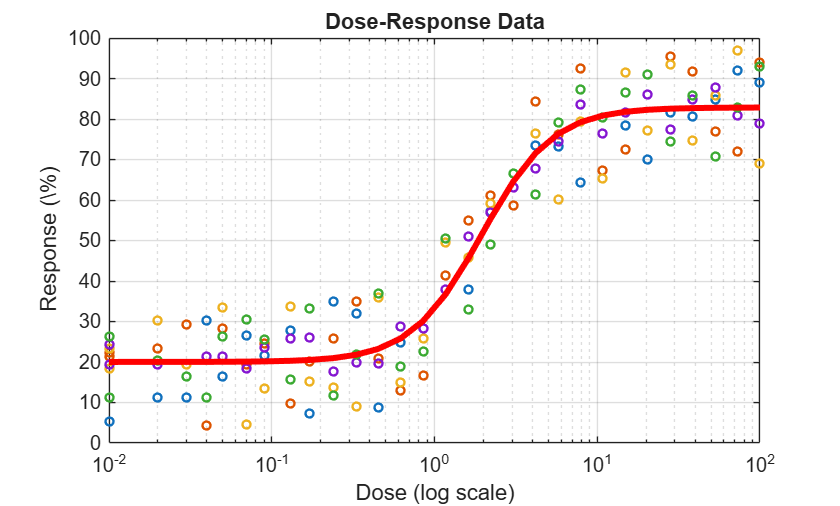

% Plot Optimized Curve
semilogx(di, HillFunc(di, xOpt), '-r', 'LineWidth', 3);
% legend('Experimental Data','','','','', 'Fitted Curve','Location','southeast');
hold off;